clear all;
clf;

## Quadcopter parameters and physical constants

global g quad_mass_kg max_thrust_N theta_deg dyn_friction_coeff cart_height_m thrust_centerline_distance_m k1_m k2_m
g = 9.81;
quad_mass_kg = 0.5;
max_thrust_N = 2*g;

k1_m = 0.01; % CoG of the quadcopter except the cable
k2_m = 24E-3; % Attachment point of the cable


theta_deg = 0;
dyn_friction_coeff = 0.14;
cart_height_m = 0.2104

cart_height_m = 0.2104

thrust_centerline_distance_m = 0.01; % TODO: CHANGE!

max_y_m = 1.44;

## LQR Setup

a = [0, -0.19*g; 1, 0];
b = [2*9.81; 0]; % Use actual value
M = [quad_mass_kg, 0; 0, 1]; % Test if including cable weight in some sort helps
A = M^-1*a;
B = M^-1*b;

Q = [0, 0; 0, 0.4/0.7];%[0, 0; 0, 1];
R = 0.3/0.7;%0.01% % Energy consumption weighting
K = lqr(A, B, Q, R)

K =     0.2328    1.0636


if false
    p = optimizableVariable('p', [0, 1.5]);
    i = optimizableVariable('i', [0, 1]);
    d = optimizableVariable('d', [0, 0.8]);
    result = bayesopt(@manyRuns, [p, i, d], "IsObjectiveDeterministic",false, 'MaxObjectiveEvaluations', 100) 
end

## Controller and path

% Waypoints as timeseries (format is (y_location, time))
waypoints = timeseries([0, 10, 100, 15, 48, 14]', [0, 5, 8, 13, 15, 19]);
load('samplemission_edited.mat')
%assert(checkTrack(waypoints), 'Track is impossible to do due to acceleration limits');


%controller = ControlSystem([1.49600751362063	1.49423390218823	0.260291881899267], waypoints)
%controller = ControlSystem([0.8, 0.6, 0.3], waypoints)
controller = LQRController(K, waypoints);

if true
    a = [1.2, 0.6, 0.3]
    a = [1.1865, 0.99865, 0.26707]
    gains.p = a(1);
    gains.i = a(2);
    gains.d = a(3);
    gains.K = K;
    manyRuns(gains)
end

a =     1.2000    0.6000    0.3000


a =     1.1865    0.9987    0.2671


ans = 0.3346

## Simulation parameters

T_max = max(waypoints.Time);
dt = 5E-4;

% Initial position and acceleration
y0 = 0;
v0 = 0;

## Simulation loop

y = y0;
v = v0;

t_arr = 0:dt:T_max;

logs.t = t_arr;
logs.y = zeros(numel(t_arr), 1);
logs.v = zeros(numel(t_arr), 1);
logs.thrust = zeros(numel(t_arr), 1);

for t_idx = 1:numel(t_arr)
    t = t_arr(t_idx);
    
    thrust = controller.calculate(y, t);
    accel = accelerationFunction(thrust, y, v);
    
    y = y + v*dt;
    v = v + accel*dt;
    
    % Make sure to not fall through the floor
    if y <= 0
        y = 0;
        v = max(0, v); % make sure v is not negative
    end
    
    if y >= max_y_m
        y = max_y_m;
        v = min(0, v); % make sure v is only negative
    end
        
    logs.y(t_idx) = y;
    logs.v(t_idx) = v;
    logs.thrust(t_idx) = thrust;
end

## Plotting

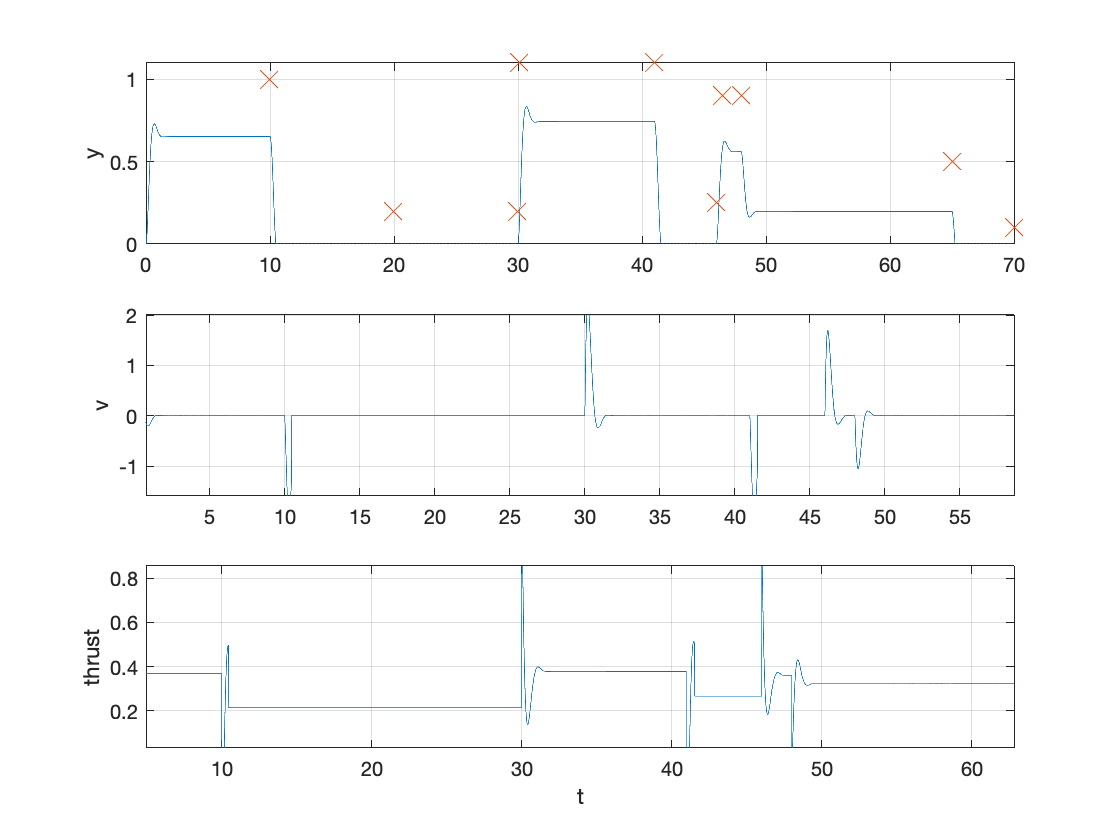

figure;

subplot(3, 1, 1);
plot(logs.t, logs.y);
grid on;
hold on;
scatter(waypoints.Time, waypoints.Data, 150, 'x');
ylabel('y')
hold off;

subplot(3, 1, 2);
plot(logs.t, logs.v);
grid on;
ylabel('v')

subplot(3, 1, 3);
plot(logs.t, logs.thrust);
grid on;
ylabel('thrust')
xlabel('t')


disp(calcAccuracy(logs, waypoints));

    0.2931



function accel = accelerationFunction(thrust, y, v) % Calculates acceleration in kgms^-2, +ve up
% TODO: Add weight of the cable track as a function of y
% TODO: Add friction
    global g quad_mass_kg max_thrust_N theta_deg dyn_friction_coeff cart_height_m thrust_centerline_distance_m k1_m k2_m;
    thrust_term = max(min(thrust, 1), 0)*max_thrust_N*cosd(theta_deg);
    cable_weight = -0.19*(y + 0.5648)*g;
    grav_term = -quad_mass_kg*g + cable_weight;
    
    total_weight_moment = grav_term*k1_m + cable_weight*k2_m;
    
    if v == 0
        % TODO: Static friciton model
        resultant = thrust_term + grav_term;
        static_friction = 0.13*g;
        if abs(resultant) < static_friction
            accel = 0;
            return;
        else
            friction_term = -sign(resultant)*static_friction;
        end
    else
        ff1 = abs(dyn_friction_coeff*(thrust_term*thrust_centerline_distance_m*cosd(theta_deg) + total_weight_moment)/cart_height_m);
        ff2 = abs(dyn_friction_coeff*(thrust_term*(cart_height_m*tand(theta_deg) - thrust_centerline_distance_m)*cosd(theta_deg) - total_weight_moment)/cart_height_m);
        
        
        friction_term = -(ff1 + ff2)*sign(v);       
    end
    
    accel = (thrust_term + grav_term + friction_term) / (quad_mass_kg - cable_weight/g);
end

function rms_accuracy = calcAccuracy(logs, waypoints)
    [~, time_indices] = min(abs(logs.t - waypoints.Time), [], 2);
    prev_idx = 1;
    err = 0;
    
    for idx_num = 1:numel(time_indices)
        idx = time_indices(idx_num);
        err = err + sum((logs.y(prev_idx:idx) - waypoints.Data(idx_num)).^2);
        prev_idx = idx;
    end
    
    %accuracies = waypoints.Data - logs.y(time_indices)
    %accuracy = logs.y - waypoints.Data
    %rms_accuracy = sqrt(mean(accuracies.^2));
    rms_accuracy = sqrt(err/numel(logs.t));
end

function randomWaypoints = randomTrack()
    n = randi([5, 15]);
    rand_height = @()(0-1.44).*rand() + 1.44;
    times = zeros(1, n);
    heights = zeros(1, n);
    
    times(1) = randi([0, 4]);
    heights(1) = rand_height();
    
    for idx = 2:n
        times(idx) = times(idx - 1) + randi([1, 5]);
        heights(idx) = rand_height();
    end
    
    randomWaypoints = timeseries(heights, times);
end

function trackWorks = checkTrack(waypoints)
    % Check if the max acceleration is lower than max thrust and min
    % deceleration is not smaller than g
    global g quad_mass_kg max_thrust_N;
    trackWorks = true;
    for idx = 2:numel(waypoints.Time)
        delta_s = waypoints.Data(idx) - waypoints.Data(idx - 1);
        delta_t = waypoints.Time(idx) - waypoints.Time(idx - 1);
        
        acc = 2*delta_s/delta_t^2;
        
        if acc < -g || acc > max_thrust_N/quad_mass_kg - g
            trackWorks = false;
            return;
        end
    end
end

function accuracy = manyRuns(gains)

    n = 20;
    accs = zeros(1, n);
    for i = 1:n
        accs(i) = oneRun(gains);
    end
    
    accuracy = mean(accs);
end

function accuracy = oneRun(gains)
    %waypoints = timeseries([1, 0.2, 0.2, 1.1, 1.1, 0.25, 0.9, 0.9, 0.5, 0.1], [10, 20, 30, 30.1, 41, 46, 46.5, 48, 65, 70]);
    waypoints = randomTrack();
    if true
        controller = LQRController(gains.K, waypoints);
    else
        controller = ControlSystem([gains.p, gains.i, gains.d], waypoints);
    end
    
    T_max = max(waypoints.Time);
    dt = 5E-4;
    max_y_m = 1.44;
    % Initial position and acceleration
    y0 = 0;
    v0 = 0;
    
    y = y0;
    v = v0;
    
    t_arr = 0:dt:T_max;
    
    logs.t = t_arr;
    logs.y = zeros(numel(t_arr), 1);
    logs.v = zeros(numel(t_arr), 1);
    logs.thrust = zeros(numel(t_arr), 1);
    
    for t_idx = 1:numel(t_arr)
        t = t_arr(t_idx);
        
        thrust = controller.calculate(y, t);
        accel = accelerationFunction(thrust, y, v);
        
        y = y + v*dt;
        v = v + accel*dt;
        
        % Make sure to not fall through the floor
        if y <= 0
            y = 0;
            v = max(0, v); % make sure v is not negative
        end
        
        if y >= max_y_m
            y = max_y_m;
            v = min(0, v); % make sure v is only negative
        end
        
        
        logs.y(t_idx) = y;
        logs.v(t_idx) = v;
        logs.thrust(t_idx) = thrust;
    end
    
    accuracy = calcAccuracy(logs, waypoints);
end